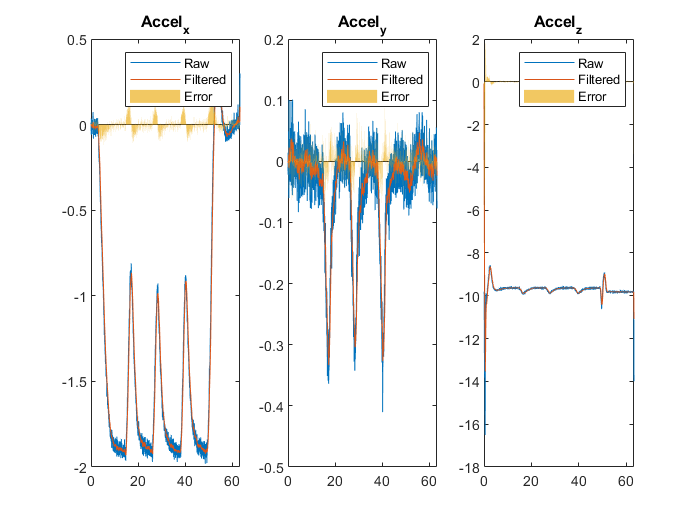

clear;
close all;
filename = 'Test3/00000631.csv';
test_data = csvread(filename, 2, 0);  

reference_motor     = 0.3; % marks when the drone takes off
max_freq            = 400; % sampling frequency
is_filter_accel     = 1;

test_data = ClipData(test_data, reference_motor, 0, 0, max_freq);

t_s         = test_data(:, 1) * 1e-6;
gyro_raw    = test_data(:, 11:13);
accel_raw   = test_data(:, 18:20);

% Filter raw accel
if is_filter_accel == 1
    fc = 1; % cut freq
    fs = max_freq; % sample freq
    [b,a] = butter(1,fc/(fs/2));
    accel_raw_filtered = filter(b,a,accel_raw);
    title_name = {'Accel_x', 'Accel_y', 'Accel_z'};
    legend_name = {'Raw', 'Filtered', 'Error'};
    plotCompareMat(t_s, accel_raw, accel_raw_filtered, title_name, legend_name, 0);
    accel_raw = accel_raw_filtered;
end

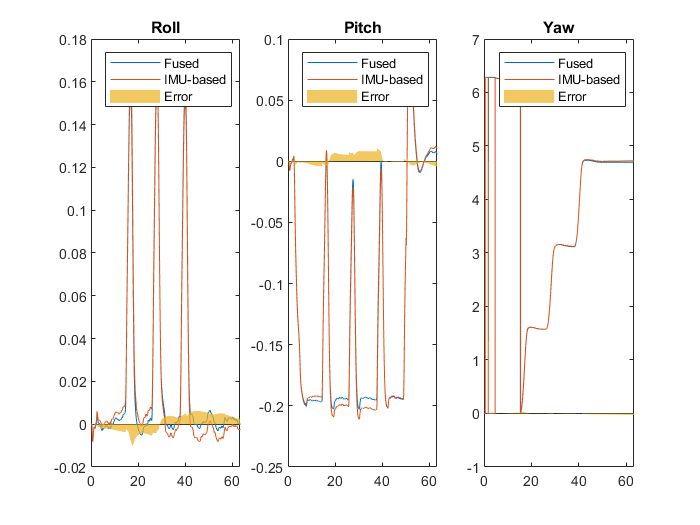


% Calculate attitude angles from gyro readings
euler_angle = getEulerFromGyro(gyro_raw, t_s);

title_name = {'Roll', 'Pitch', 'Yaw'};
legend_name = {'Fused', 'IMU-based', 'Error'};
fused_eulers = test_data(:, 5:7);
plotCompareMat(t_s, fused_eulers, euler_angle, title_name, legend_name, 1);

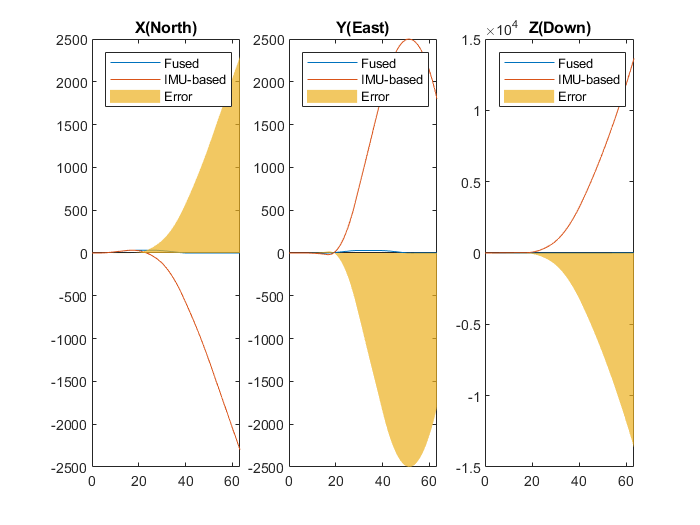


% Calculate acceleration in earth frame with known attitude from gyro
accel_ef = transBf2Ef(accel_raw, euler_angle);
accel_ef(:, 3) = accel_ef(:, 3) + 9.8;

fused_pos = test_data(:, 2:4);
fused_vel = test_data(:, 8:10);
start_time = 0; % unit: seconds
[position, velocity] =  getPosFromAccel(t_s, accel_ef, fused_pos, fused_vel, start_time);

title_name = {'X(North)', 'Y(East)', 'Z(Down)'};
legend_name = {'Fused', 'IMU-based', 'Error'};
plotCompareMat(t_s, fused_pos, position, title_name, legend_name, 0);

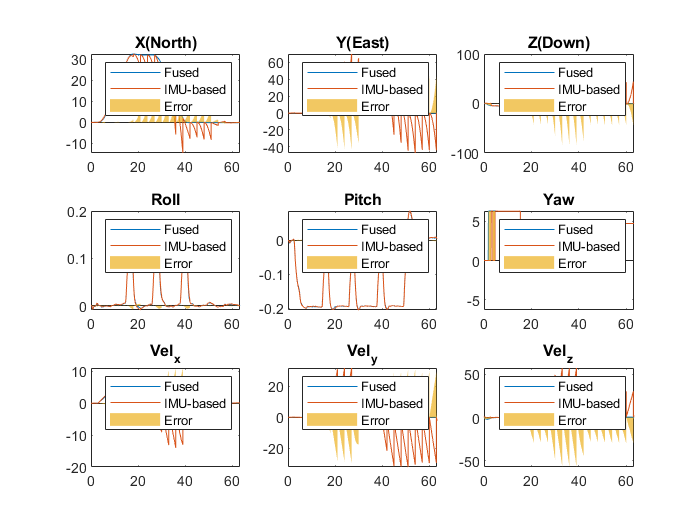

% Calculate step by step with possible synchronization

fused_states    = test_data(:, 2:10);
sync_K          = 3 * max_freq;         % unit: samples
start_time      = 0;                    % unit: seconds

[position, attitude, velocity] =  getPosFromIMU(t_s, accel_raw, gyro_raw, fused_states, sync_K, start_time);
IMU_states = [position, attitude, velocity];

title_name = {'X(North)', 'Y(East)', 'Z(Down)', 'Roll', 'Pitch', 'Yaw', 'Vel_x', 'Vel_y', 'Vel_z'};
legend_name = {'Fused', 'IMU-based', 'Error'};
plotCompareMat(t_s, fused_states, IMU_states, title_name, legend_name, 0);

function euler_angle = getEulerFromGyro(gyro, time)
euler_angle = zeros(size(gyro, 1), 3);
dt = diff(time);
for i = 1:(size(gyro,1)-1)
    phi = euler_angle(i,1);
    theta = euler_angle(i,2);
    psi = euler_angle(i, 3);
    trans_mat = [1, sin(phi)*tan(theta), cos(phi)*tan(theta);
        0, cos(phi), -sin(phi);
        0, sin(phi)/cos(theta), cos(phi)/cos(theta)];
    d_euler = (trans_mat * gyro(i, :)')';
    euler_angle(i+1, :) = euler_angle(i, :) + d_euler * dt(i);
end
euler_angle(:, 3) = wrapTo2Pi(euler_angle(:, 3));
end

function data_ef = transBf2Ef(data_bf, euler_angle)
    rotm = eul2rotm(euler_angle, 'ZYX');
    data_ef = zeros(size(data_bf, 1),3);
    for i = 1:size(data_bf,1)
        data_ef(i, :) = (rotm(:,:,i) * data_bf(i, :)')';
    end
end

function plotCompareMat(x_axis, A_data, B_data, title_name, legend_name, is_wrapPi)
    figure;
    N = size(A_data,2);
    for i=1:N
        subplot(ceil(N/3),3,i);
        plot(x_axis, A_data(:, i));
        hold on;
        plot(x_axis, B_data(:, i));
        hold on;
        if is_wrapPi
            error = wrapToPi(A_data(:, i) - B_data(:, i));
        else
            error = A_data(:, i) - B_data(:, i);
        end
%         yyaxis right
        area(x_axis, error , 'FaceAlpha', 0.7, 'EdgeColor','none');
        legend(legend_name);
        title(title_name(i));
    end
end


function [position, velocity] =  getPosFromAccel(time, accel, pos_gt, vel_gt, start_time)
    start_idx = find(time >= start_time, 1);
    position = zeros(size(pos_gt, 1), 3);
    velocity = zeros(size(vel_gt, 1), 3);
    position(1:start_idx, :) = pos_gt(1:start_idx, :);
    velocity(1:start_idx, :) = vel_gt(1:start_idx, :);
    
    accel_cut = accel(start_idx:end, :);
    time_cut = time(start_idx:end, :);
    
    delta_v = accel_cut(1:end-1, :) .* diff(time_cut);
    delta_v_cum = cumsum(delta_v);
    velocity(start_idx+1:end, :) = vel_gt(start_idx, :) + delta_v_cum;
    vel_cut = velocity(start_idx:end, :);
    delta_pos = vel_cut(1:end-1, :) .* diff(time_cut);
    delta_pos_cum = cumsum(delta_pos);
    position(start_idx+1:end, :) = pos_gt(start_idx, :) + delta_pos_cum;
end

function [position, attitude, velocity] =  getPosFromIMU(t_s, accel_raw, gyro_raw, states_gt, sync_K, start_time)
    x_gt = states_gt';
    gyro_bf = gyro_raw';
    accel_bf = accel_raw';
    x = zeros(size(x_gt));
    x(:, 1) = x_gt(:, 1);
    N = size(x, 2);
    for i = 2:N
        dt = t_s(i) - t_s(i-1);
        dx = states_odefun(x(:, i-1), accel_bf(:, i-1), gyro_bf(:, i-1));
        x(:, i) = x(:, i-1) + dx * dt;
        x(6, i) = wrapTo2Pi(x(6, i));
        % sync for before start_time
        if i * dt < start_time
            x(:, i) = x_gt(:, i);
        end
        
        % K-step sync
        if sync_K > 0 && mod(i, sync_K) == 0
            x(:, i) = x_gt(:, i);
        end
    end
    position = x(1:3, :)';
    attitude = x(4:6, :)';
    velocity = x(7:9, :)';
end


function dx = states_odefun(x, accel_bf, gyro_bf)
% all input are column vectors
%  x: 1:3 postion,  4:6 euler angles,       7:9 velocity
% dx: 1:3 velocity, 4:6 euler angles rate,  7:9 acceleration
    g = 9.80665;
    dx = zeros(size(x));
    dx(1) = x(7);
    dx(2) = x(8);
    dx(3) = x(9);
        phi = x(4);
        theta = x(5);
        psi = x(6);
        trans_mat = [1, sin(phi)*tan(theta), cos(phi)*tan(theta);
            0, cos(phi), -sin(phi);
            0, sin(phi)/cos(theta), cos(phi)/cos(theta)];
    dx(4:6) = trans_mat * gyro_bf;
    dx(7:9) = eul2rotm(x(4:6)', 'ZYX') * accel_bf + [0, 0, g]';
    
end